# Everything Together: Simulink, Simscape, and Transfer Functions (S-Domain)

## Task #1: Understand the Project Scope: Build a Simulink/SimScape Model Using 3 Strategies

The objective of this project is to build a simulink/simscape model using 3 different strategies: (1) Transfer Function in the Laplace Domain, (2) time domain in Simulink, (3) physical modeling using SimScape.

Consider a simple mass spring damper system as shown below:

               Assume M = 1 Kg, b = 1 Ns/m, k =1 N/m

                                                                      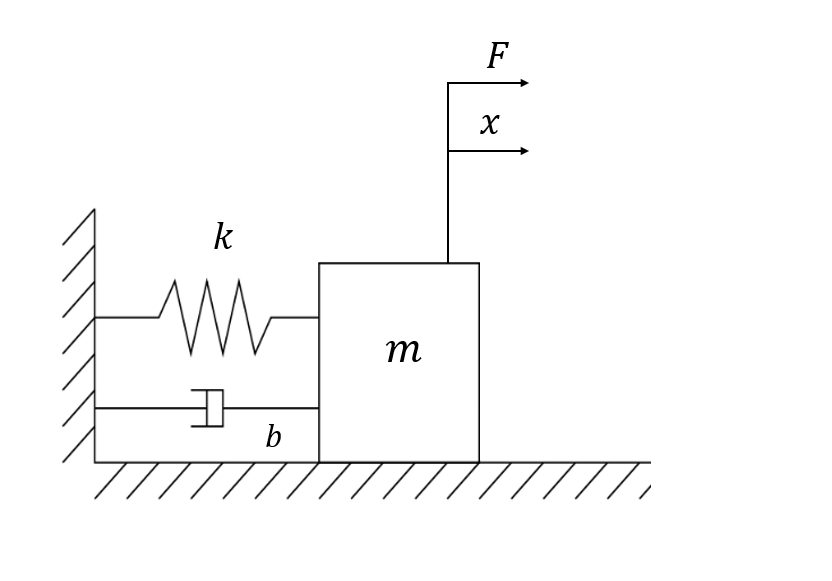

**Strategy #1:** Using Simlink in the Time Domain

                                                                                    
$$\textrm{Mx}̈=F-\textrm{bx}̇-\textrm{kx}$$


**Strategy #2:** Using Transfer Functions in the S-Domain

                                                                        
$${\textrm{Ms}}^{2\;} X\left(s\right)=F\left(s\right)-\textrm{bsX}\left(s\right)-\textrm{kX}\left(s\right)$$


                                                                                        
$$\frac{X\left(s\right)}{F\left(s\right)}=\frac{1}{{\textrm{Ms}}^2 +\textrm{bs}+k}$$


**Strategy #3:** Using Physical Modeling Techniques such as SimScape

## Task #2: Build a Simulink/SimScape Model Using 3 Strategies

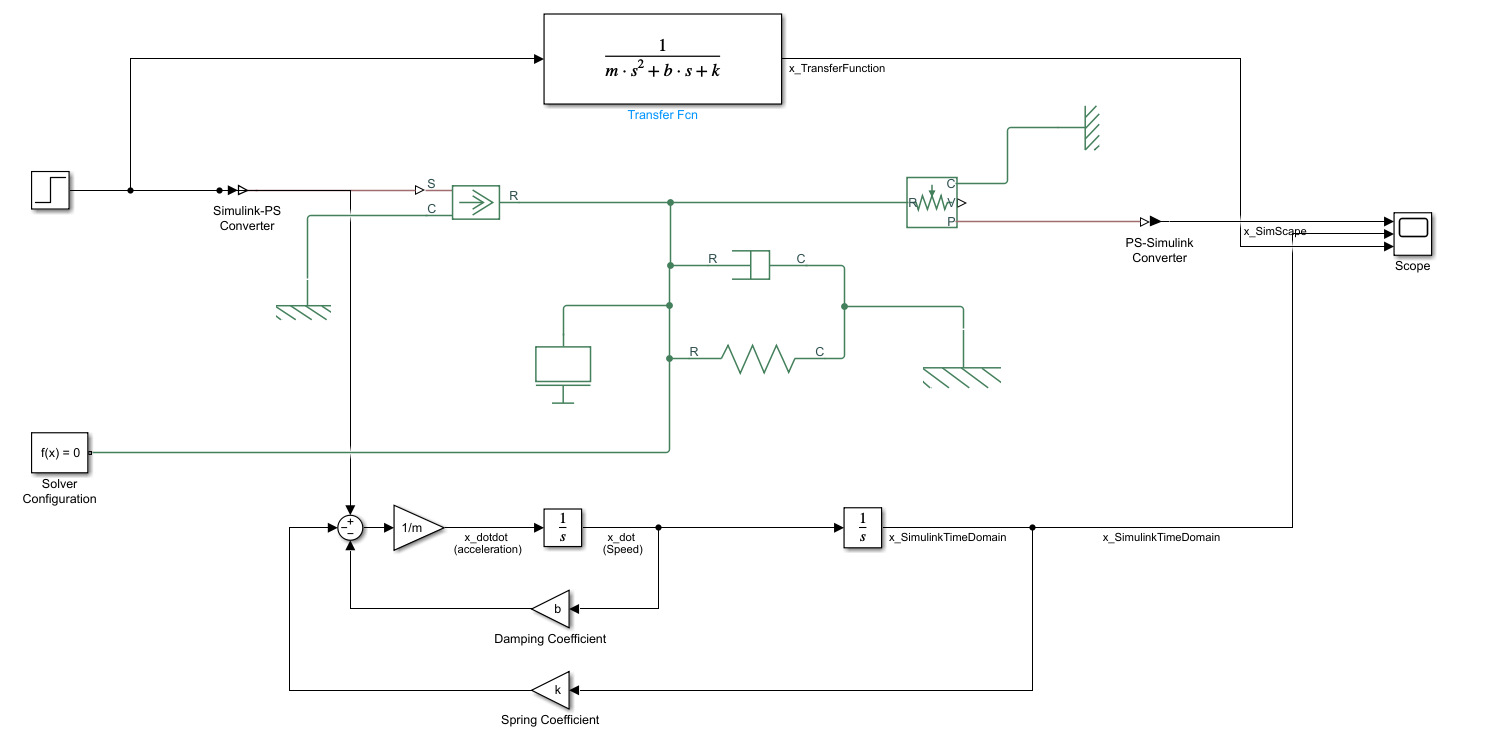

## Task #3: Simulate the Model Using 3 Strategies and Perform Sanity Check

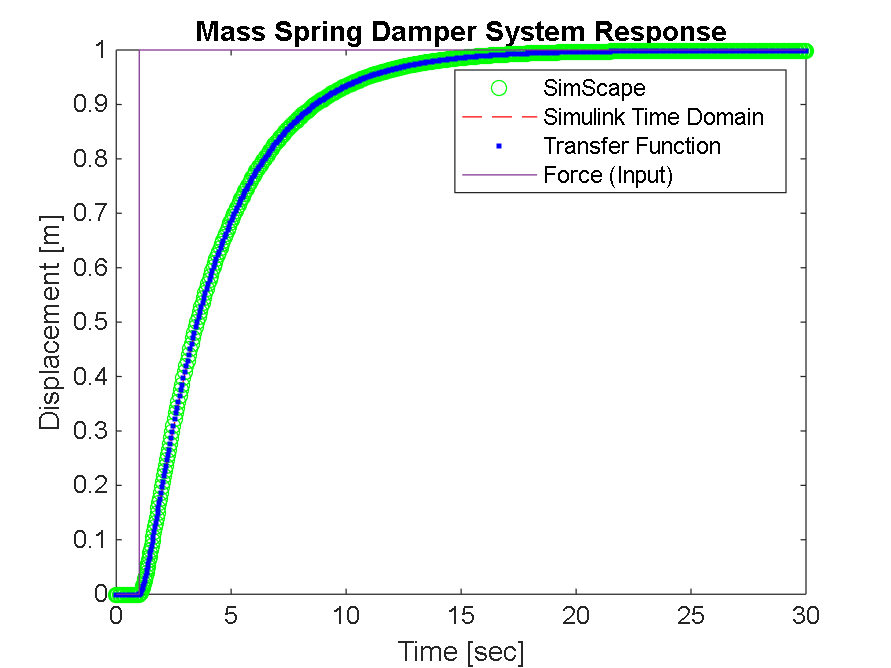


% Define Model Parameters
Sim_Time = 30;
F = 1;
m = 1;
b =3.5;
k = 1;


sim('mass_spring_damper_simulink_simscape.slx');


figure
plot(x_SimScape, 'go')
hold on 
plot(x_SimulinkTimeDomain, 'r--')
hold on 
plot(x_TransferFunction, 'b.')
hold on 
plot(Force)
hold on 
ylabel('Displacement [m]')
xlabel('Time [sec]')
title('Mass Spring Damper System Response')
legend('SimScape','Simulink Time Domain', 'Transfer Function', 'Force (Input)')

## Final Capstone Project Overview

In this final capstone project, please complete the following tasks: 

- Build a two degrees of freedom mechanical system using three techniques: (1) transfer function blocks in Simulink, (2) simscape, and (3) time domain in Simulink. 

- Plot the displacement x1, x2, and Force (input) for all 3 proposed strategies on one graph, confirm that all outputs are similar. Try several mass and damping coefficients values to confirm your results. 

             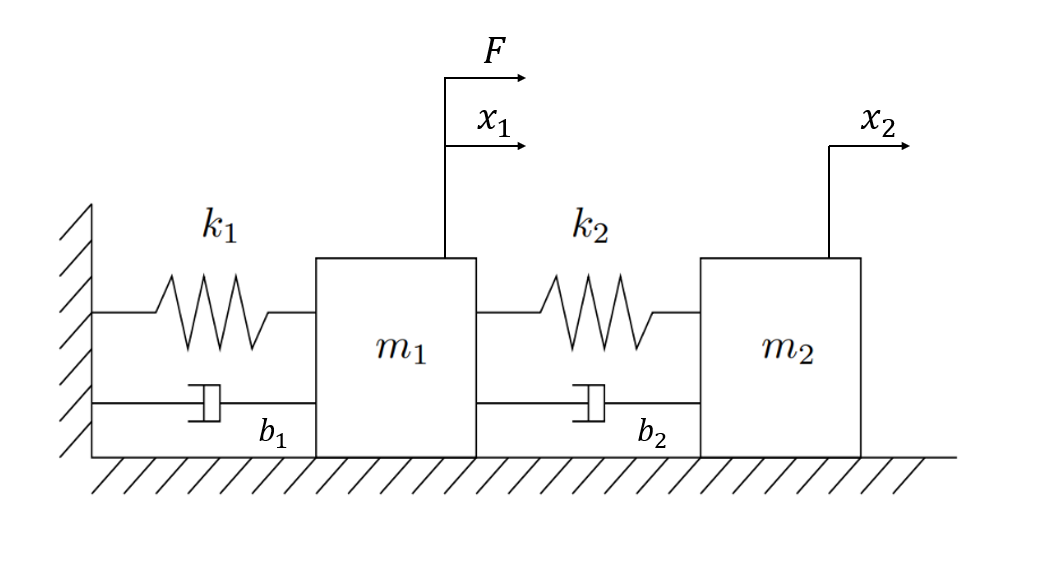

Note that the systems contains two masses m1 and m2, two springs with spring constants k1 and k2, and two dampers with damping coefficients b1 and b2. Where m1 = 1 Kg, b1 = 1 Ns/m, k1 = 1 N/m, m2 = 1 Kg, b2 = 1 Ns/m, k2 = 1 N/m, apply a unit step input F and simulate the system.

## Final Capstone Project Solution

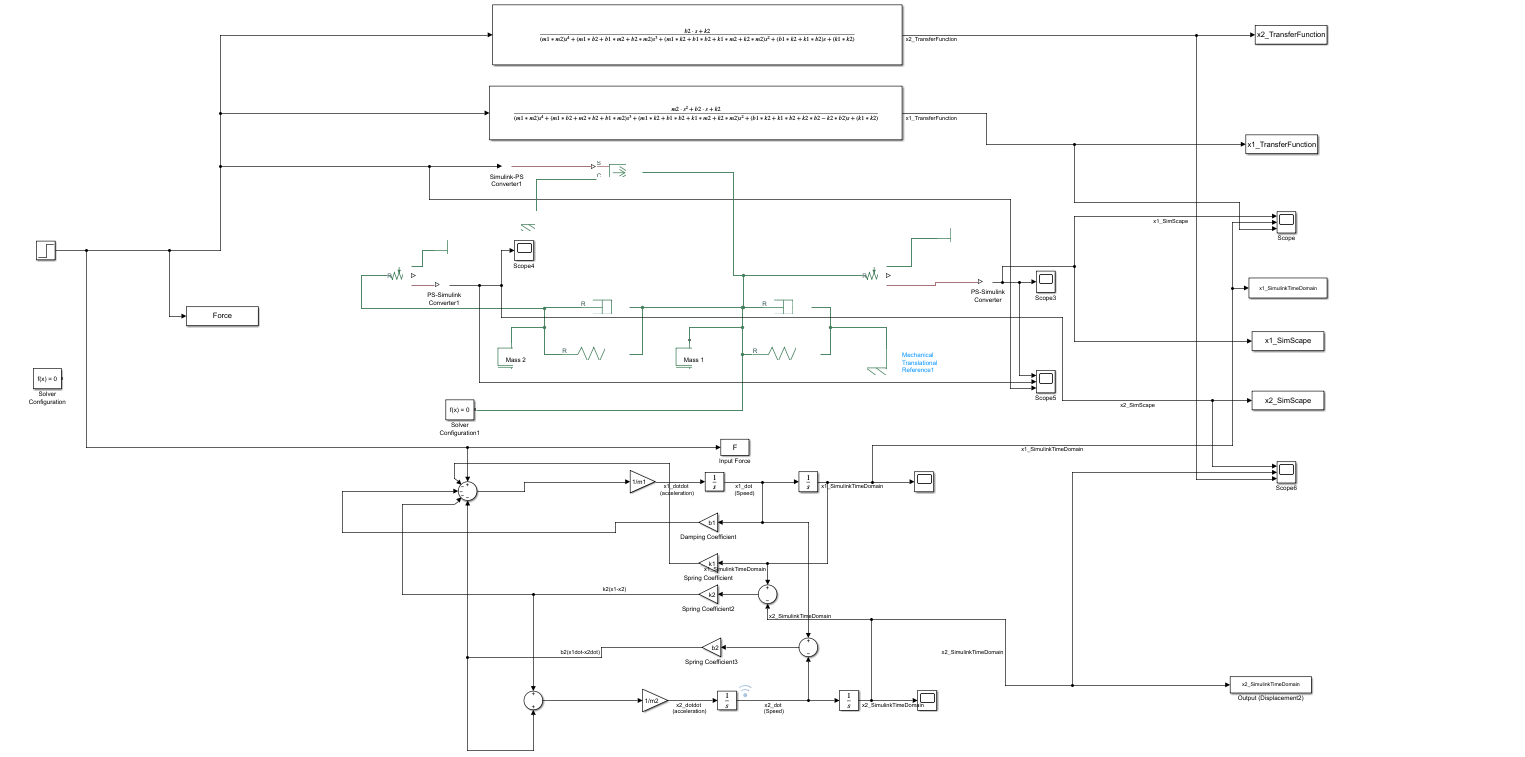

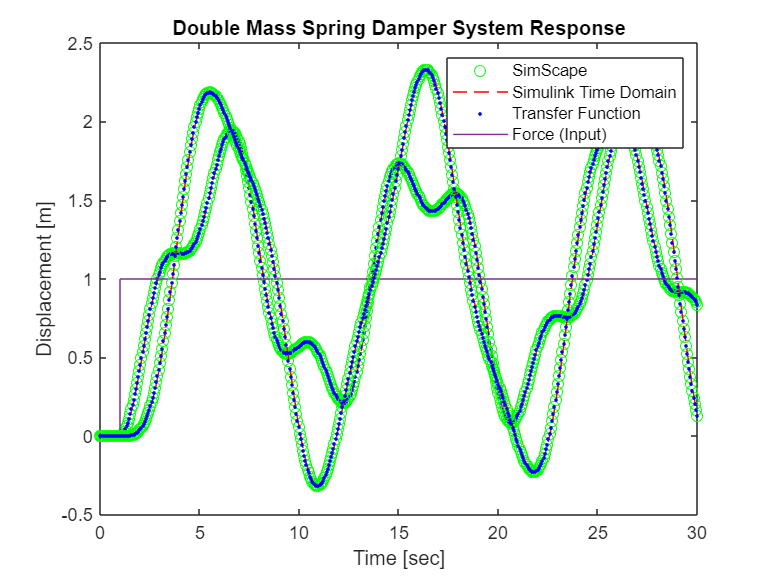

% Define Model Parameters
Sim_Time = 25;
F = 1;
m1 = 1;
b1 =0;
k1 = 1;

m2 = 1;
b2 =0;
k2 = 1;

sim('mass_spring_damper_simulink_simscape_project_solution.slx');


figure
plot(x1_SimScape, 'go')
hold on 
plot(x1_SimulinkTimeDomain, 'r--')
hold on 
plot(x1_TransferFunction, 'b.')
hold on 
plot(Force)
hold on 


plot(x2_SimScape, 'go')
hold on 
plot(x2_SimulinkTimeDomain, 'r--')
hold on 
plot(x2_TransferFunction, 'b.')
hold on 


ylabel('Displacement [m]')
xlabel('Time [sec]')
title('Double Mass Spring Damper System Response')
legend('SimScape','Simulink Time Domain', 'Transfer Function', 'Force (Input)')

## Great Job!